# **Root Locus: General Equation**


$$\frac{\overset{\ldotp }{\theta} }{V}\;=\frac{K}{\left(\textrm{Js}+K_d \right)\left(\textrm{Ls}+R\right)+K^2 }$$



$$K=K_f {\;K}_g$$



$$$\text{where} \\ L = \text{Inductance} \\ V= \text{Voltage} \\ J = \text{Moment of Inertia} \\ K_g = \text{Gear Ratio} \\ K_f = \text{Back EMF Constant} \\ R = \text{Resistance}\\K_d  = \text{Damping Coefficient} \\ $$$
                    
$$$\text{where} \\L = 1 \times 10^{-5} \, H \\J = 8.6 \, kg \cdot m^2 \\K_g = 2000 \\ K_f = 0.07\\R = 10 \, \Omega \\K_d = 5 \, Nm \cdot rad^{-1} \cdot s^{-1} \\ \\ $$$


num = 140;
denum = [(8.6*10^-5) (86.00005) (19650)];
sys_0 = zpk([], denum, num)

sys_0 =
 
                140
  -------------------------------
  (s-8.6e-05) (s-86) (s-1.965e04)
 
Continuous-time zero/pole/gain model.



sys = tf(num ,denum)

sys =
 
             140
  --------------------------
  8.6e-05 s^2 + 86 s + 19650
 
Continuous-time transfer function.



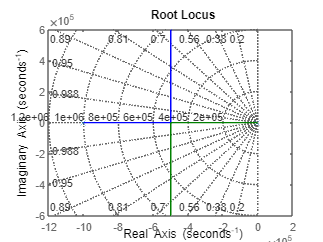

rlocus(sys)
grid on

%sisotool(sys)